Question 1

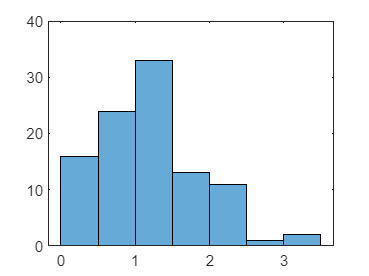

% Number of points
n = 100;

% Generate RVs
x = randn(1,n); 
y = randn(1,n);
z = x+j*y;
magZ = abs(z);

% Plot
pdf = histogram(magZ);

Question 2

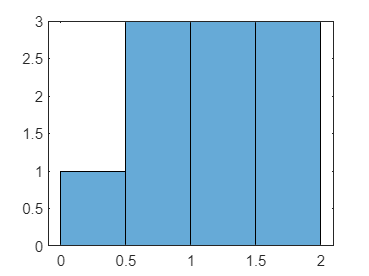

n2a = 10;
x2a = randn(1,n2a);
y2a = randn(1,n2a);
z2a = x2a+j*y2a;
magZ2a = abs(z2a);
pdf2a = histogram(magZ2a);

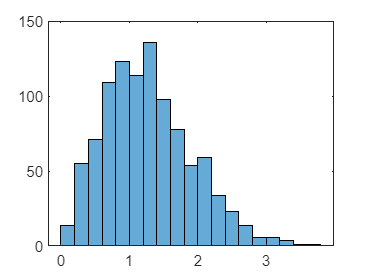


n2b = 1000;
x2b = randn(1,n2b);
y2b = randn(1,n2b);
z2b = x2b+j*y2b;
magZ2b = abs(z2b);
pdf2b = histogram(magZ2b);

Question 3

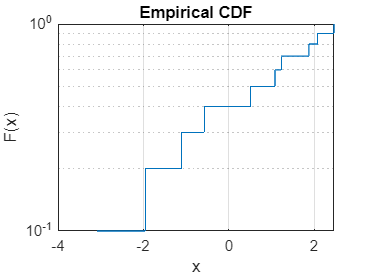

% CDF10a = cdfplot(magZ2a);
% set(gca, 'YScale', 'log');
% set(gca, 'XScale', 'log');
CDF10 = cdfplot(magZ2a);
CDF10.XData = real(10.*log10(CDF10.XData));
set(gca, 'YScale', 'log')

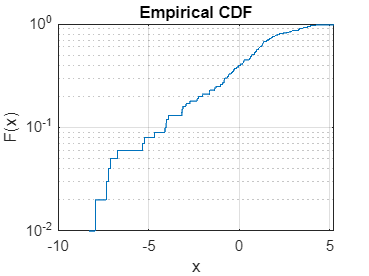

CDF100 = cdfplot(magZ);
CDF100.XData = real(10.*log10(CDF100.XData));
set(gca, 'YScale', 'log')

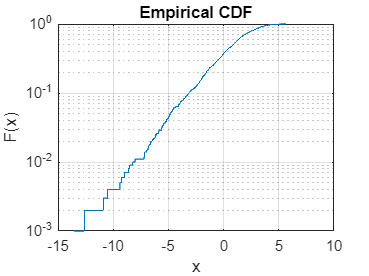

CDF1000 = cdfplot(magZ2b);
CDF1000.XData = real(10.*log10(CDF1000.XData));
set(gca, 'YScale', 'log')

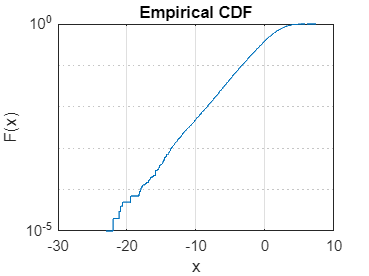


n3 = 100000;
x3 = randn(1,n3);
y3 = randn(1,n3);
z = x3+j*y3;
magZ3 = abs(z);
CDF3 = cdfplot(magZ3);
CDF3.XData = real(10.*log10(CDF3.XData));
set(gca, 'YScale', 'log')

Question Four

numberOfComponents = [1, 2, 3, 5, 10];
numberOfPoints = 1000;
Amplitude = 1;
multipathSignal = zeros([numberOfPoints, k]);
for k = 1:length(numberOfComponents)
    for m = 1:numberOfPoints
        phases = rand([1 numberOfComponents(k)]);
        phases = 2*pi*phases;
        
        x = exp(j*phases);
        x = sum(x);
        x = x/(Amplitude*numberOfComponents(k));
        multipathSignal(m, k) = x;      
    end
    subplot(2,1,1)
    histogram(abs(multipathSignal(:,k)),'Normalization','pdf')
    grid on
    hold on
    subplot(2,1,2)
    [h, stats] = cdfplot(abs(multipathSignal(:,k)));
    set(gca,'YScale','log')
    set(gca,'XScale','log')
    hold on
    grid on
end



Question Five

numberOfComponents = [1, 2, 3, 5, 10];
numberOfPoints = 1000;
Amplitude = 1;
multipathSignal = zeros([numberOfPoints, k]);
for k = 1:length(numberOfComponents)
    for m = 1:numberOfPoints
        phases = rand([1 numberOfComponents(k)]);
        phases = 2*pi*phases;
        amplitudes = rand([1 numberOfComponents(k)]);
        
        x = amplitudes.*exp(j*phases);
        x = sum(x);
        x = x/(Amplitude*numberOfComponents(k));
        multipathSignal(m, k) = x;      
    end
    subplot(2,1,1)
    histogram(abs(multipathSignal(:,k)),'Normalization','pdf')
    grid on
    hold on
    subplot(2,1,2)
    [h, stats] = cdfplot(abs(multipathSignal(:,k)));
%     set(gca,'YScale','log')
%     set(gca,'XScale','log')
    hold on
    grid on
end



Question Five B

numberOfComponents = [1, 2, 3, 5, 10];
numberOfPoints = 1000;
Amplitude = 1;
multipathSignal = zeros([numberOfPoints, k]);
for k = 1:length(numberOfComponents)
    for m = 1:numberOfPoints
        phases = rand([1 numberOfComponents(k)]);
        phases = 2*pi*phases;
        amplitudes = raylrnd(1, [1 numberOfComponents(k)]);
        
        x = amplitudes.*exp(j*phases);
        x = sum(x);
        x = x/(Amplitude*numberOfComponents(k));
        multipathSignal(m, k) = x;      
    end
    subplot(2,1,1)
    histogram(abs(multipathSignal(:,k)),'Normalization','pdf')
    grid on
    hold on
    subplot(2,1,2)
    [h, stats] = cdfplot(abs(multipathSignal(:,k)));
    set(gca,'YScale','log')
    set(gca,'XScale','log')
    hold on
    grid on
end




Question Six A

numberOfPoints = 100;
K = [1, 2, 10];
numberOfPoints = 10000;
sigma = 1;

r = zeros([numberOfPoints, length(K)]);
for k = 1:length(K)
    nu = K(k)*2*sigma^2;
    nu = sqrt(nu);
    x = sigma .* randn([numberOfPoints 1]) + nu;
    y = sigma .* randn([numberOfPoints 1]);
    r(:, k) = sqrt(x.^2 + y.^2);
    subplot(2,1,1)
    histogram(r(:,k),'Normalization','pdf')
    grid on
    hold on
    subplot(2,1,2)
    [h, stats] = cdfplot(r(:,k));
    set(gca,'YScale','log')
    set(gca,'XScale','log')
    hold on
    grid on
    
end

Question Six B

numberOfPoints = 10;
K = [1, 2, 10];
numberOfPoints = 10000;
sigma = 1;

r = zeros([numberOfPoints, length(K)]);
for k = 1:length(K)
    nu = K(k)*2*sigma^2;
    nu = sqrt(nu);
    x = sigma .* randn([numberOfPoints 1]) + nu;
    y = sigma .* randn([numberOfPoints 1]);
    r(:, k) = sqrt(x.^2 + y.^2);
    subplot(2,1,1)
    histogram(r(:,k),'Normalization','pdf')
    grid on
    hold on
    subplot(2,1,2)
    [h, stats] = cdfplot(r(:,k));
    set(gca,'YScale','log')
    set(gca,'XScale','log')
    hold on
    grid on
    
end


Question Six C

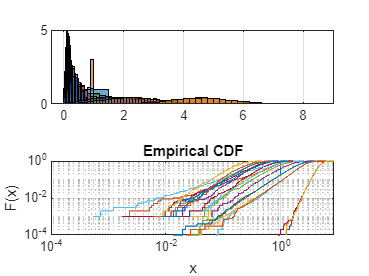

numberOfPoints = 1000;
K = [1, 2, 10];
numberOfPoints = 10000;
sigma = 1;

r = zeros([numberOfPoints, length(K)]);
for k = 1:length(K)
    nu = K(k)*2*sigma^2;
    nu = sqrt(nu);
    x = sigma .* randn([numberOfPoints 1]) + nu;
    y = sigma .* randn([numberOfPoints 1]);
    r(:, k) = sqrt(x.^2 + y.^2);
    subplot(2,1,1)
    histogram(r(:,k),'Normalization','pdf')
    grid on
    hold on
    subplot(2,1,2)
    [h, stats] = cdfplot(r(:,k));
    set(gca,'YScale','log')
    set(gca,'XScale','log')
    hold on
    grid on
    
end